# Bicubic prolongation

This live script provides examples of the bicubic prolongation method.

### Plot on coarse grid

We choose the function as


$$f(x,y) = \sin(\pi x)\sin(\pi y)$$


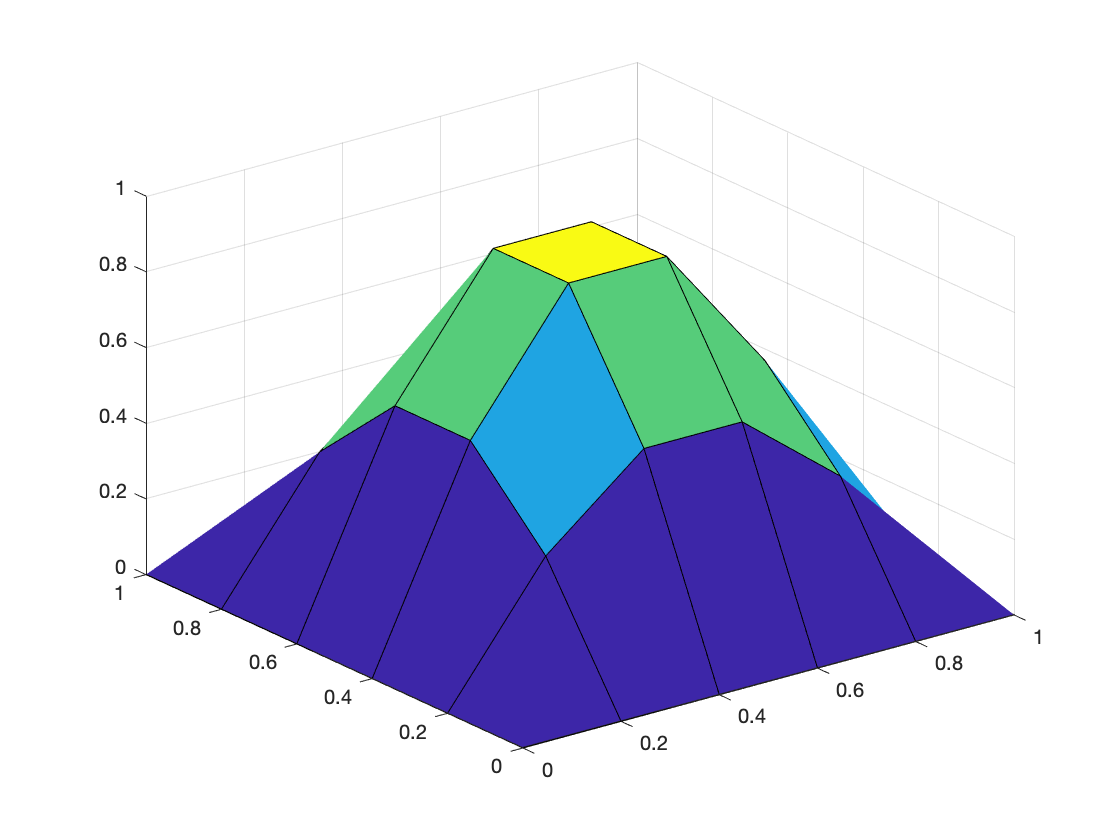

[x,y] = meshgrid(0:0.2:1,0:0.2:1);
z = sin(pi.*x) .* sin(pi.*y);
surf(x,y,z)

### Bicubic prolongation with exact derivatives

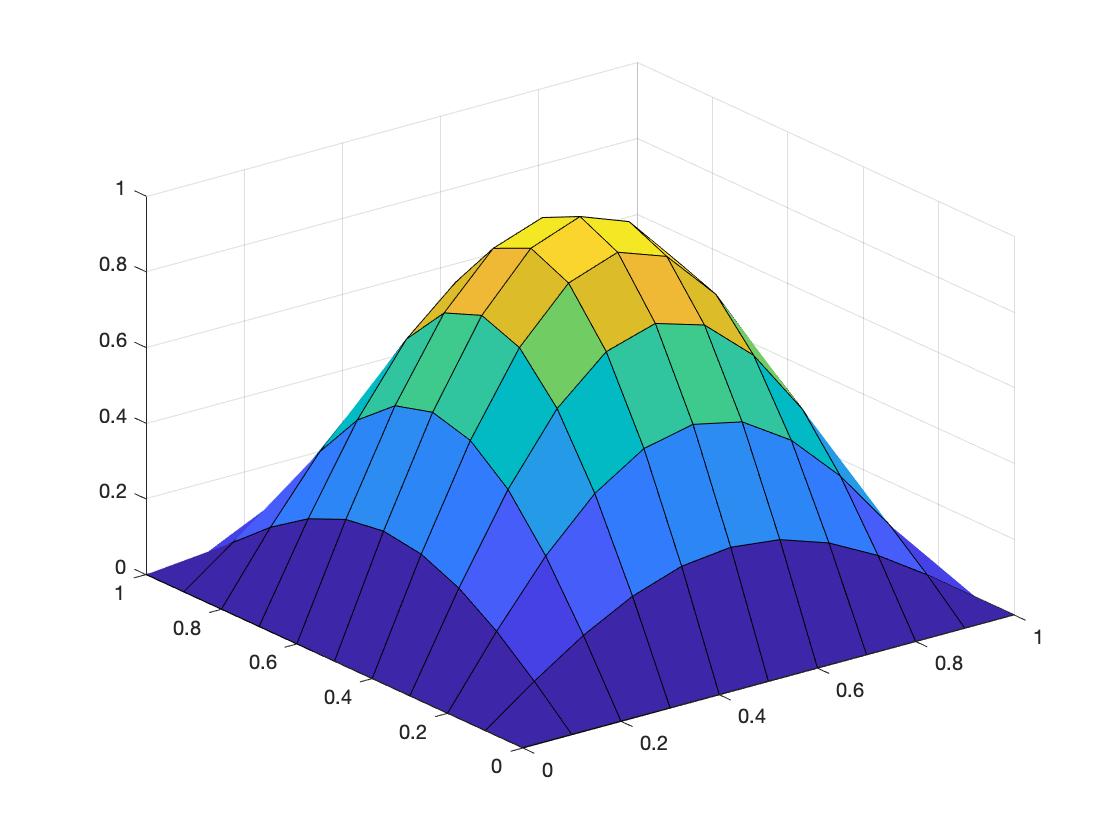

A = [1,0,0,0;0,0,1,0;-3,3,-2,-1;2,-2,1,1];
B = [1,0,-3,2;0,0,3,-2;0,1,-2,1;0,0,-1,1];
F = @(x,y) sin(pi.*x) .* sin(pi.*y);
Fx = @(x,y) pi .* cos(pi*x) .* sin(pi*y);
Fy = @(x,y) pi .* sin(pi*x) .* cos(pi*y);
Fxy = @(x,y) pi * pi .* cos(pi*x) .* cos(pi*y);

[X,Y] = meshgrid(0:0.1:1,0:0.1:1);
R = sin(pi.*X) .* sin(pi.*Y);

Z = zeros(11,11);
for i = 1:6
    for j = 1:6
        Z(2*i-1,2*j-1) = z(i,j);
    end
end
resizex = 1 / (x(1,2) - x(1,1));
resizey = 1 / (y(2,1) - y(1,1));
for i = 1:5
    for j = 1:5
        f = F(x(i:i+1,j:j+1),y(i:i+1,j:j+1))';
        fx = Fx(x(i:i+1,j:j+1),y(i:i+1,j:j+1))' / resizex;
        fy = Fy(x(i:i+1,j:j+1),y(i:i+1,j:j+1))' / resizey;
        fxy = Fxy(x(i:i+1,j:j+1),y(i:i+1,j:j+1))' / resizex / resizey;
        C = [f,fy;fx,fxy];
        P = A*C*B;
        Z(2*i,2*j-1) = [1,0,0,0] * P * [1;0.5;0.5^2;0.5^3];
        Z(2*i,2*j) = [1,0.5,0.5^2,0.5^3] * P * [1;0.5;0.5^2;0.5^3];
        Z(2*i,2*j+1) = [1,1,1,1] * P * [1;0.5;0.5^2;0.5^3];
        Z(2*i-1,2*j) = [1,0.5,0.5^2,0.5^3] * P * [1;0;0;0];
        Z(2*i+1,2*j) = [1,0.5,0.5^2,0.5^3] * P * [1;1;1;1];
    end
end
surf(X,Y,Z)

### Bicubic prolongation with approximated derivatives.

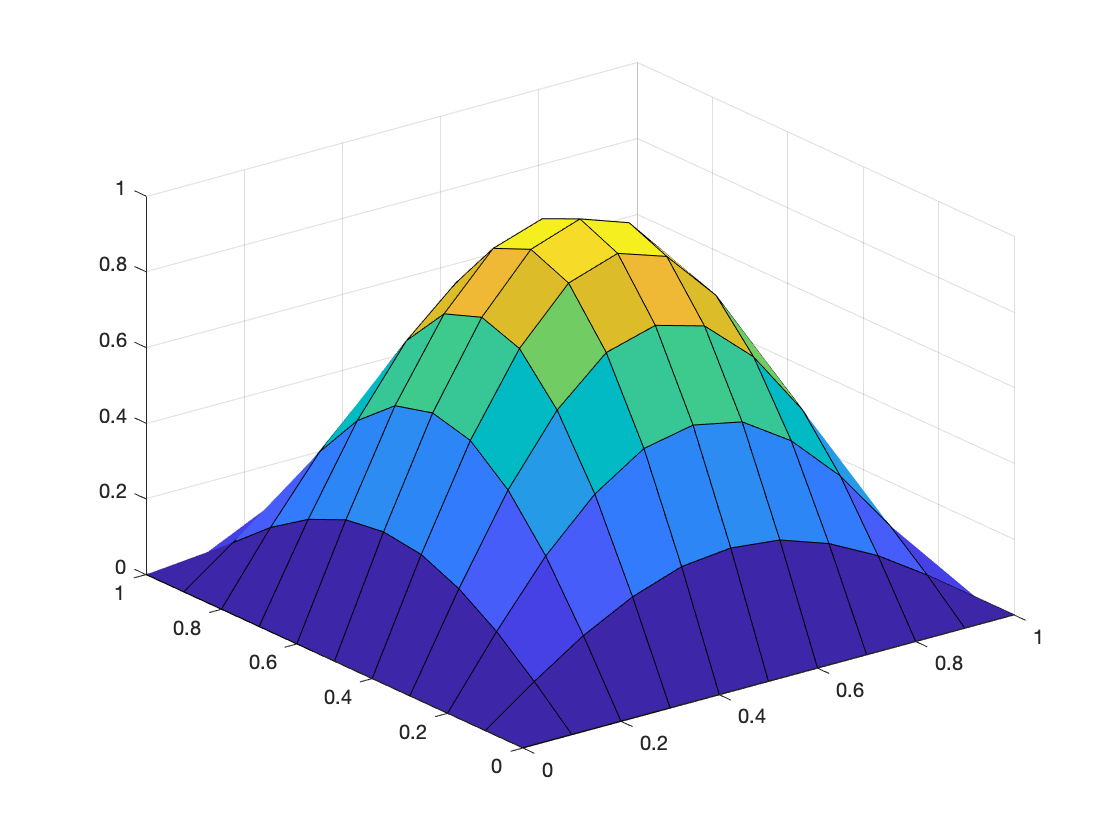

A = [1,0,0,0;0,0,1,0;-3,3,-2,-1;2,-2,1,1];
B = [1,0,-3,2;0,0,3,-2;0,1,-2,1;0,0,-1,1];
F = z;
mesh_size = size(z);
deltax = x(1,2) - x(1,1);
deltay = y(2,1) - y(1,1);
Fx = zeros(mesh_size); Fy = zeros(mesh_size); Fxy = zeros(mesh_size);
for i = 1:mesh_size(1)
    Fx(i,1) = (z(i,2) - z(i,1)) / deltax;
    for j = 2:mesh_size(2)-1
        Fx(i,j) = (z(i,j+1) - z(i,j-1)) / (2 * deltax);
    end
    Fx(i,mesh_size(2)) = (z(i,mesh_size(2)) - z(i,mesh_size(2)-1)) / deltax;
end
for j = 1:mesh_size(2)
    Fy(1,j) = (z(2,j) - z(1,j)) / deltay;
    for i = 2:mesh_size(1)-1
        Fy(i,j) = (z(i+1,j) - z(i-1,j)) / (2 * deltay);
    end
    Fy(mesh_size(1),j) = (z(mesh_size(1),j) - z(mesh_size(1)-1,j)) / deltay;
end
Fxy(1,1) = (z(2,2) - z(1,2) - z(2,1) + z(1,1)) / (deltax * deltay);
for j = 2:mesh_size(2)-1
    Fxy(1,j) = (z(2,j+1) - z(1,j+1) - z(2,j-1) + z(1,j-1)) / (2 * deltax * deltay);
end
Fxy(1,mesh_size(2)) = (z(2,mesh_size(2)) - z(1,mesh_size(2)) - z(2,mesh_size(2)-1) + z(1,mesh_size(2)-1)) / (deltax * deltay);
for i = 2:mesh_size(1)-1
    Fxy(i,1) = (z(i+1,2) - z(i-1,2) - z(i+1,1) + z(i-1,1)) / (2 * deltax * deltay);
    for j = 2:mesh_size(2)-1
        Fxy(i,j) = (z(i+1,j+1) - z(i-1,j+1) - z(i+1,j-1) + z(i-1,j-1)) / (4 * deltax * deltay);
    end
    Fxy(i,mesh_size(2)) = (z(i+1,mesh_size(2)) - z(i-1,mesh_size(2)) - z(i+1,mesh_size(2)-1) + z(i-1,mesh_size(2)-1)) / (2 * deltax * deltay);
end
Fxy(mesh_size(1),1) = (z(mesh_size(1),2) - z(mesh_size(1)-1,2) - z(mesh_size(1),1) + z(mesh_size(1)-1,1)) / (deltax * deltay);
for j = 2:mesh_size(2)-1
    Fxy(mesh_size(1),j) = (z(mesh_size(1),j+1) - z(mesh_size(1)-1,j+1) - z(mesh_size(1),j-1) + z(mesh_size(1)-1,j-1)) / (2 * deltax * deltay);
end
Fxy(mesh_size(1),mesh_size(2)) = (z(mesh_size(1),mesh_size(2)) - z(mesh_size(1)-1,mesh_size(2)) - z(mesh_size(1),mesh_size(2)-1) + z(mesh_size(1)-1,mesh_size(2)-1)) / (deltax * deltay);

[X,Y] = meshgrid(0:0.1:1,0:0.1:1);
Z = zeros(11,11);
for i = 1:6
    for j = 1:6
        Z(2*i-1,2*j-1) = z(i,j);
    end
end
resizex = 1 / (x(1,2) - x(1,1));
resizey = 1 / (y(2,1) - y(1,1));
for i = 1:5
    for j = 1:5
        f = F(i:i+1,j:j+1)';
        fx = Fx(i:i+1,j:j+1)' / resizex;
        fy = Fy(i:i+1,j:j+1)' / resizey;
        fxy = Fxy(i:i+1,j:j+1)' / resizex / resizey;
        C = [f,fy;fx,fxy];
        P = A*C*B;
        Z(2*i,2*j-1) = [1,0,0,0] * P * [1;0.5;0.5^2;0.5^3];
        Z(2*i,2*j) = [1,0.5,0.5^2,0.5^3] * P * [1;0.5;0.5^2;0.5^3];
        Z(2*i,2*j+1) = [1,1,1,1] * P * [1;0.5;0.5^2;0.5^3];
        Z(2*i-1,2*j) = [1,0.5,0.5^2,0.5^3] * P * [1;0;0;0];
        Z(2*i+1,2*j) = [1,0.5,0.5^2,0.5^3] * P * [1;1;1;1];
    end
end
surf(X,Y,Z)